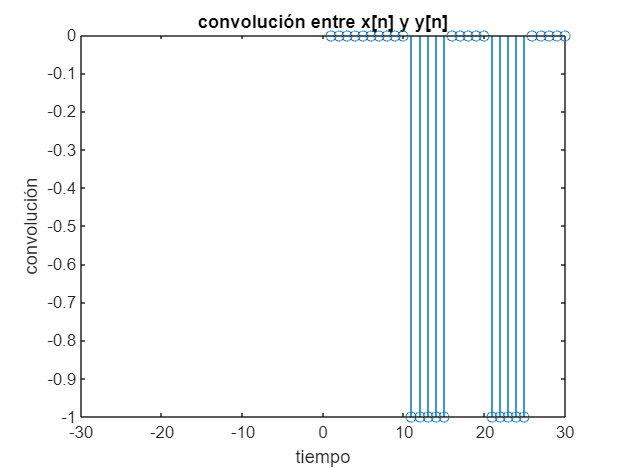

n = -10:10;
t = -5:15;
u1 = escalon_unitario(n);
u2 = escalon_unitario(n,-5);
xn = u1 - u2;
d1 = delta_dirac(t);
d2 = delta_dirac(t-10);
yn = d1+d2;
convolucion = convolucion_manual(xn, yn);
xlim([-30, 30]);

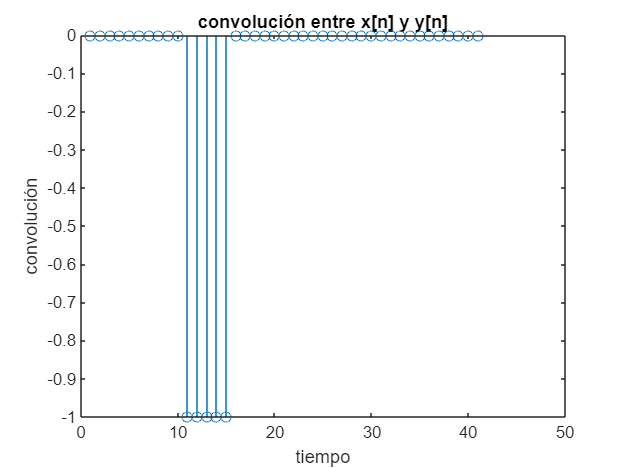

stem(convolucion);
xlabel('tiempo');
ylabel('convolución');
title('convolución entre x[n] y y[n]');